JPEG Assignment Ahmed El Melegy,,

Start of Assignment....... 

this assignment will be divided into instruction and below is the code.

Steps.......

1- Read and divide the image into blocks of 8x8 pixels.

i assumed the input image is divisible by 8 ,,this image is 64*64 , the original image was 400 **400 but due to my laptop cannot handle this image size i cropped it to 64 *64,,, you can change to work on flower image not resized one by change first line of code to "flower.jpg" but i don't recommend as it needs much processing time .*

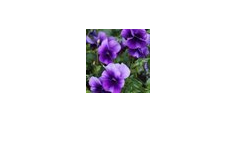

% read the image and convert it to gray scale
input_img=imread('rsz_flower.jpg');
imshow(input_img);

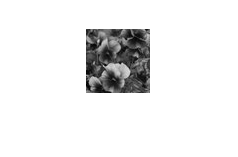

rgb_img_=rgb2gray(input_img);
imwrite(rgb_img_, 'input_image.jpg');
imshow(rgb_img_);

% convert it to double instead of uint8 and get size
rgb_img=double(rgb_img_);
[row ,col]=size(rgb_img);

2.Perform DCT on each block 8by 8

the general formula is 

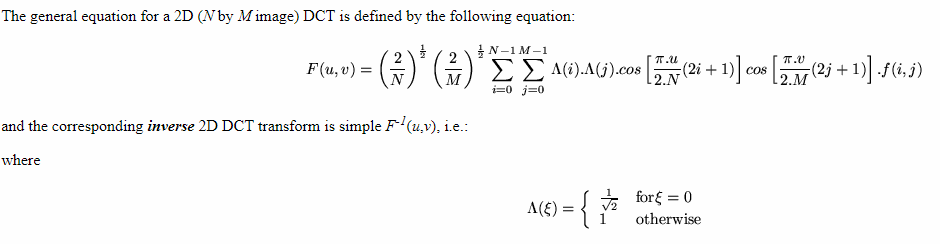

% compute DCT
dct_img=zeros(row,col); %intizlize dct image

%divide it into 8by 8 blocks
for b_row=1:8:row
    for b_col=1:8:col %the first two loops to divide the image int 8by8 block
        % DCT on each block 
        z=1;
        for x=b_row:1:b_row+7
            c=1;
            for y=b_col:1:b_col+7 % the second two loops for indices of dct matrix
                vv=1;
                for u=b_row:1:b_row+7 %the third two loops to loop input image vertically and horzontialy  
                    b=1;
                    for v=b_col:1:b_col+7
                        dct_img(x,y)=dct_img(x,y)+rgb_img(u,v)*cos((2*(b-1)+1)*(c-1)*pi/16)*cos((2*(vv-1)+1)*(z-1)*pi/16);
                        b=b+1;
                    end
                    vv=vv+1;
                    
                end
                    if ((z-1)==0)
                        alpha=1/sqrt(2);
                    else
                        alpha=1;
                    end
                    if ((c-1)==0) 
                        beta=1/sqrt(2);
                    else
                        beta=1;
                    end
                    dct_img(x,y)=dct_img(x,y)*alpha*beta/4;
                    c=c+1;
            end
            z=z+1;
        end
    end
end

Perform the quantization step per 8x8 block using at least two quantization tables

first i will use two quantization table from (https://www.impulseadventure.com/photo/jpeg-quantization-lookup.html?src1=26799) for IPHONE

Just first to play around (then i will use the table that give me the compression specifications )

%% note this part has done after finish all assignment then i started to put my compression specification ,,first i want 

specs 1 (this for high compression less space and low quality)

1.ssimval (image quality) explained in details below to be higher than 0.9 (quality to be above 90%, the 100% quality is my input image which is my reference )

2.CR=uncompressed size/compressed size >1.2 (>1 there is compression has been done)

OR 

space saving=1-1/CR >20%( the compressed image has 15% of image size less than uncompressed image )

specs 2 (this for low compression high space and high quality)

1.ssimval >98

2.CR > 1 OR space saving >1%

% Here i will define two quantiztion table these two tables used by apple
Q_spec=[16 12 14 18 99 40 5 61;
        22 25 24 18 100 32 64 55;
        14 4 18 16 103 64 128 56;
        18 18 16 32 64 128 128 62;
        16 16 32 64 109 128 256 77;  
        32 32 64 128 128 256 256 92;
        64 64 128 128 103 256 256 101;
        72 92 95 98 112 100 103 99;];% this quantization table meet my specs 1
Q_spec2=[4 4 6 12 15 17 21 24;
         4 5 6 16 17 19 22 24;
         6 6 14 19 21 24 24 24;
         11 16 24 24 24 24 24 24;
         24 24 24 24 24 28 28 28;
         24 24 24 24 24 28 28 32;
         24 24 24 24 24 28 28 32;
         24 24 28 28 28 32 32 32;];%this quantization table meet my specs 2
    
% Quantization ... divide each 8by8 block by the Q_table
for i=1:8:row
    for j=1:8:col
        quan_img(i:i+7,j:j+7)= dct_img(i:i+7,j:j+7)./Q_spec;
    end
end
quan_img=round(quan_img); 

these two quantization table i reconstructed them from the tables in the book for high compression and from the link above for low compression to my specs..

4.Transform each block from 2-D into 1-D vector using the following pattern (zig -zag shape)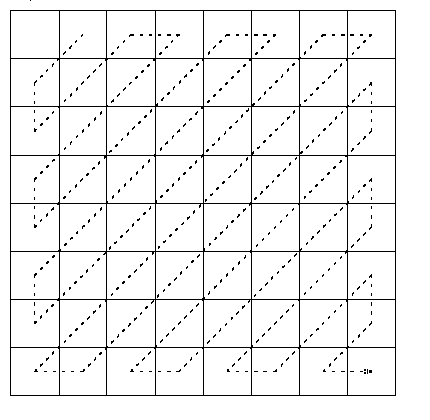

%zig-zag order for 8by 8 block  from the above image is
%(1,1),(1,2),(2,1),(3,1),(2,2) and so on
block_index_row=0;
zigzaged_blocks=zeros(row*col/64,64); %each block is zigzaged so total is 64*64/64=64 row
for i=1:8:row
    for j=1:8:col
        block_index_row=block_index_row+1;
        sub_block=quan_img(i:i+7,j:j+7);
        zigzaged_blocks(block_index_row,:)=[sub_block(1,1),sub_block(1,2),sub_block(2,1),sub_block(3,1),sub_block(2,2),sub_block(1,3),sub_block(1,4),sub_block(2,3),sub_block(3,2),sub_block(4,1),sub_block(5,1),sub_block(4,2),sub_block(3,3),sub_block(2,4),sub_block(1,5),sub_block(1,6),sub_block(2,5),sub_block(3,4),sub_block(4,3),sub_block(5,2),sub_block(6,1),sub_block(7,1),sub_block(6,2),sub_block(5,3),sub_block(4,4),sub_block(3,5),sub_block(2,6),sub_block(1,7),sub_block(1,8),sub_block(2,7),sub_block(3,6),sub_block(4,5),sub_block(5,4),sub_block(6,3),sub_block(7,2),sub_block(8,1),sub_block(8,2),sub_block(7,3),sub_block(6,4),sub_block(5,5),sub_block(4,6),sub_block(3,7),sub_block(2,8),sub_block(3,8),sub_block(4,7),sub_block(5,6),sub_block(6,5),sub_block(7,4),sub_block(8,3),sub_block(8,4),sub_block(7,5),sub_block(6,6),sub_block(5,7),sub_block(4,8),sub_block(5,8),sub_block(6,7),sub_block(7,6),sub_block(8,5),sub_block(8,6),sub_block(7,7),sub_block(6,8),sub_block(7,8),sub_block(8,7),sub_block(8,8)];
    end
end
% zigzaged_blocks is now 64*64 each row is zigzaged block

5.Use run-length encoding to compress the stream of zeros that may results due to the quantization

warning('off','all')
warning

All warnings have the state 'off'.


% first define run length code function and inverse run length code,encode
% and decode ,defined in the last section of this notebook
for each_block=1:1:row*col/64
        data(each_block,:)=run_length_code(zigzaged_blocks(each_block,:));% extract every 8by block ,,each row 8by 8 block
        arrdata=cell2mat(data(each_block,2));% convert it from array to cell as my run length code need it as cell
        probaba=arrdata./sum(arrdata);%calculate the probability of each unique symbol as run length code will return the unique values 
        dict=huffmandict(arrdata,probaba);% call built in huffmandict to make the dictionary
        coded_seq=huffmanenco(arrdata,dict);%call built in huffmanencod built in function to encode each block with the given dictionary 
        decoded_seq=huffmandeco(coded_seq,dict);%deocde with the built in function with the given dictionary
        datacell=cell2mat(data(each_block,1));
        databack={datacell decoded_seq};% convert them to cell to run length code 
        retrived_img(each_block,:)=run_length_code(databack);%call run length code function and store in retrived image 
        arrdata=[];
        probaba=[];
        dict={};
        coded_seq=[];               % empty these temps for the new block 
        decoded_seq=[]; 
        datacell=[];
        databack={};
end


% here i will do the reverse of the zigzag to construct the image as 8by8
% groups ,,, unzigzaged order to construct the same order is
% temp(1),temp(2),temp(6)...
% temp(3),(temp(5),temp(8)... from the above image 
% this becuase each block is zigzaged as one row 
block_index=1;
un_zigzaged_blocks=zeros(row*col/64,64);
for i=1:8:row
    for j=1:8:col
        temp=retrived_img(block_index,:);
        un_zigzaged_blocks_temp=[temp(1),temp(2),temp(6),temp(7),temp(15),temp(16),temp(28),temp(29);
                                 temp(3),temp(5),temp(8),temp(14),temp(17),temp(27),temp(30),temp(43);
                                 temp(4),temp(9),temp(13),temp(18),temp(26),temp(31),temp(42),temp(44);
                                 temp(10),temp(12),temp(19),temp(25),temp(32),temp(41),temp(45),temp(54);
                                 temp(11),temp(20),temp(24),temp(33),temp(40),temp(46),temp(53),temp(55);
                                 temp(21),temp(23),temp(34),temp(39),temp(47),temp(52),temp(56),temp(61);
                                 temp(22),temp(35),temp(38),temp(48),temp(51),temp(57),temp(60),temp(62);
                                 temp(36),temp(37),temp(49),temp(50),temp(58),temp(59),temp(63),temp(64)];
        un_zigzaged_blocks(i:i+7,j:j+7)=un_zigzaged_blocks_temp;
        block_index=block_index+1;
    end
end

6.Dequantization (multiply each block by the corresponding quantization table 

% then multiply each 8by8 group by the quantization table 
for i=1:8:row
    for j=1:8:col
        de_quan_img(i:i+7,j:j+7)= un_zigzaged_blocks(i:i+7,j:j+7).*Q_spec;
    end
end

7.IDCT  from the general formula ..

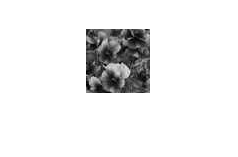

%IDCT
idct_img=zeros(row,col); %intizlize dct image
    for b_row=1:8:row
        for b_col=1:8:col       %the first two loops to divide them into 8by8 blocks
            z_idct=1;
            for x=b_row:1:b_row+7
                c_idct=1;
                for y=b_col:1:b_col+7   %the second two loops for (x,y) indices for idct matrix
                    v_idct=1;
                    for u=b_row:1:b_row+7
                        b_idct=1;
                        for v=b_col:1:b_col+7 %the third two loops for (u,v) to loop on the input image 
                            if ((v_idct-1)==0)
                                Ci=1/sqrt(2);
                            else
                                Ci=1;
                            end
                            if ((b_idct-1)==0)
                                Cj=1/sqrt(2);
                            else
                                Cj=1;
                            end
                            idct_img(x,y)=idct_img(x,y)+de_quan_img(u,v)*Ci*Cj*cos((2*(c_idct-1)+1)*(b_idct-1)*pi/16)*cos((2*(z_idct-1)+1)*(v_idct-1)*pi/16);
                            b_idct=b_idct+1;
                        end
                        v_idct=v_idct+1;
                    end        
                    idct_img(x,y)=idct_img(x,y)/4;
                    c_idct=c_idct+1;
                end
                z_idct=z_idct+1;
            end
        end
    end
out_imag=uint8(idct_img);
imshow(out_imag);

imwrite(out_imag, 'out_image.jpg');

image quality and compression ration

i used the built in function ssim depend on the documentation description

"Structural similarity (SSIM) index. The SSIM metric combines local image structure, luminance, and contrast into a single local quality score. In this metric,*structures* are patterns of pixel intensities, especially among neighboring pixels, after normalizing for luminance and contrast. Because the human visual system is good at perceiving structure, **the SSIM quality metric agrees more closely with the subjective quality score**." 

1.[https://www.mathworks.com/help/images/image-quality-metrics.html](https://www.mathworks.com/help/images/image-quality-metrics.html)

2.[https://www.mathworks.com/help/images/ref/ssim.html](https://www.mathworks.com/help/images/ref/ssim.html)

ssimval= ssim(out_imag,rgb_img_);
disp("Structural similarity (SSIM) index for measuring image quality");

Structural similarity (SSIM) index for measuring image quality


ssimval

ssimval = 0.9170

function compressedORdecompressed = run_length_code(compressORdecompress)
% run length code (encoder) will be counting each unique number and count
% how many it is repeated then return two cell one for the unique number
% another cell is for the number of repetition of the corresponding unique
% number ,,,decoder will be just multiply the number with corresponding
% repetition number from the other cell,,,
if iscell(compressORdecompress) % if the input data is cell i will decode it ,,array i will encode it 
	uncompressedORcompressed_arr_size = cumsum([ 1 compressORdecompress{2} ]);%get the cumulative sum of x{2} to  the help me in temp to get actual size of uncompressed array( i will use the last entry to do so)
	temp = zeros(1, uncompressedORcompressed_arr_size(end)-1); %initialize temp to be the (1.last entry-1) this the actual size of uncompressed data
	temp(uncompressedORcompressed_arr_size(1:end-1)) = 1;%make the indices get from uncompressedORcompressed_arr_size to be =1
	compressedORdecompressed = compressORdecompress{1}(cumsum(temp));  % then get the deocding sequence by the cumulative sum to  temp as it has ones's at the indices get from uncompressedORcompressed_arr_size and zero's else where 
else % it has one cell i will encode it
if (size(compressORdecompress,1) > size(compressORdecompress,2))% if x is a column vector, tronspose it
compressORdecompress = compressORdecompress'; %transpose
end 
    uncompressedORcompressed_arr_size = [ find(compressORdecompress(1:end-1) ~= compressORdecompress(2:end)) length(compressORdecompress) ];% here i find the indices of unique values e.g. input is [1 1 2 2 3 3 4] out is [2 4 6 7] indices of unique values 
	compressedORdecompressed{2} = diff([ 0 uncompressedORcompressed_arr_size ]);% this will return Y = [X(2)-X(1) X(3)-X(2) ... X(m)-X(m-1)] which is how many unique value is repeted as uncompressedORcompressed_arr_size has the indices of uniques values 
	compressedORdecompressed{1} = compressORdecompress(uncompressedORcompressed_arr_size);%return the unique values 
end
end

Note: i calculate the image size from windows itself from the properties  of the image it has size,, for example at specs 2 input image size was 1.71KB and output image was 1.69KB  and quality=0.98

(which meet my specs 2)

and for specs 1 input image was 1.71KB and output image was 1.42KB and quality =0.91

(which meet my specs 1) 

note 1 : to change from specs to specs 2 just do the following

- at line 69 change Q_spec to Q_spec2

- at line 131 change Q_spec2 to Q_spec2

note 2:i see the calculation of the size of my image is an extra work i don't need as windows show the size of the image .

note 3 : i assumed my input image is gray scale not the RGB image 

End of Assignment....... 

JPEG Assignment Ahmed El Melegy,,